%%
clf 

model='Drone_2M_sim_V6_linmod'

model = 'Drone_2M_sim_V6_linmod'

%open_system(model)
clear io

io(1) = linio('Drone_2M_sim_V6_linmod/Control units/Roll ref',1,'input');
io(2) = linio('Drone_2M_sim_V6_linmod/Control units/Roll ang',1,'output');
io(3) = linio('Drone_2M_sim_V6_linmod/Control units/Pitch ref',1,'input');
io(4) = linio('Drone_2M_sim_V6_linmod/Control units/Pitch ang',1,'output');
io(5) = linio('Drone_2M_sim_V6_linmod/Control units/Yaw ref',1,'input');
io(6) = linio('Drone_2M_sim_V6_linmod/Control units/Yaw velocity',1,'output');
%io(7) = linio('Drone_2M_sim_V6_linmod/Control units/height_control/height ctrl1',1,'input');
%io(8) = linio('Drone_2M_sim_V6_linmod/Control units/height_control/heightVelLp',1,'output');
%io(7) = linio('Drone_2M_sim_V6_linmod/acc-x',1,'output');
io(7) = linio('Drone_2M_sim_V6_linmod/Control units/yawMixer',1,'input'); %only for use in cross coupling
%io(8) = linio('Drone_2M_sim_V6_linmod/Control units/u_pitch',1,'input'); %only for use in cross coupling

%X-position

io


1x7 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: Drone_2M_sim_V6_linmod/Control units/Roll ref
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: Drone_2M_sim_V6_linmod/Control units/Roll ang
- Port: 1
- Signal Name: Roll ang
3. Linearization input perturbation located at the following signal:
- Block: Drone_2M_sim_V6_linmod/Control units/Pitch ref
- Port



servoAngleFeedBack=1; calibServo=0.7 %0.7

calibServo = 0.7000

stepYaw=0;      yawStepSize=15;
stepRoll=0;
stepPitch=0;    pitchStepSize=15;
stepServo=0;    servoStepSize=deg2rad(10);
rightDeadBandWidthDeg=0;%10;
leftDeadBandWidthDeg=0;%15;
noiseOn=0;
servoTimesSlower=1;%makes the servo's x times slower;Defualt=1;
%batteryPositionOffset=-1/100; %in meters

[linsys,linop] = linearize(model,io,[6]) 

linsys =
 
  A = 
                 Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim  Drone_2M_sim
   Drone_2M_sim             0             0             0             0             0             1             0             0
   Drone_2M_sim             0             0             0             0             0             0             0             1
   Drone_2M_sim             0             0     1.859e-07    -0.0003864     0.0006667             0             0             0
   Drone_2M_sim             0             0     0.0003853     1.493e-06     0.0003052             0             0             0
   Drone_2M_sim             0             0    -0.0006669    -0.0003044    -6.927e-08             0             0             0
   Drone_2M_sim          -439         3.037       0.07285        -115.2       -0.1027         -87.8    -8.894e-13        0.6075
   Drone_2M_sim         0.159       -0.2206        -18.84         0.045      0.004103 

linop =  Operating point for the Model Drone_2M_sim_V6_linmod.
 (Time-Varying Components Evaluated at time t=6)

States: 
----------
     x     
___________
           
(1.) Drone_2M_sim_V6_linmod.x6_DOF_Joint1.Px.p
 -0.31165  
(2.) Drone_2M_sim_V6_linmod.x6_DOF_Joint1.Py.p
  1.2216   
(3.) Drone_2M_sim_V6_linmod.x6_DOF_Joint1.Pz.p
  1.0037   
(4.) Drone_2M_sim_V6_linmod.x6_DOF_Joint1.S.Q
     1     
-0.00060889
 0.0022395 
-0.00017956
(5.) Drone_2M_sim_V6_linmod.x6_DOF_Joint1.Px.v
  0

%det sidste argument er til hvilke tidspunkter skal den linerarisere. 
%step(linsys)

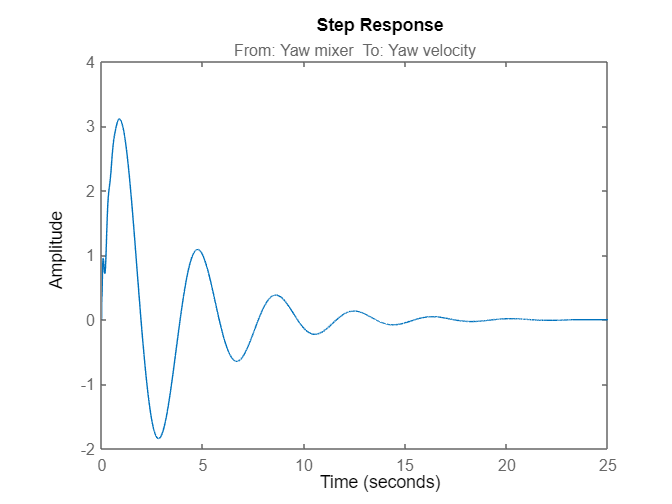

%save("linearizeModelOldAndNew","linsysNew","linsysOld")


clf
%systemOrder=length(linsys.A)
%minreal(H(1,1))
H=(tf(linsys));
%step(H(1,1)) %roll
%step(H(2,2)) %pitch
%step(H(3,3)) %yaw
%step(H(4,4)) %height
step(H(3,4))

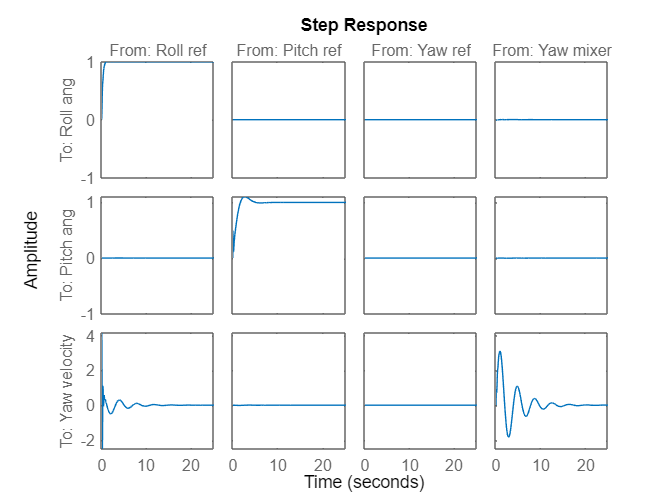


%step(H(2,5))
step(H)

%trandfer func
H(1,1);
defaltTol=sqrt(eps)

defaltTol =    1.4901e-08


tol=1.5e-2

tol =         0.015


[num,denum]=tfdata(minreal(H(1,1),tol),'v');
order=length(denum)

order =     10


%state space:
%tol=1.5e1000000
order=length(minreal(linsys,tol).A) %fjerner ikke nok states

10 states removed.


order = 26

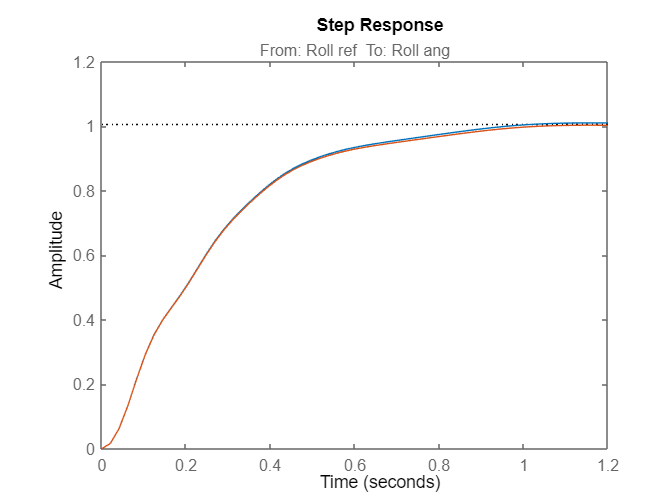

%step
clf
step(minreal(H(1,1),tol)) %roll
hold on
step(H(1,1)) %roll
hold off

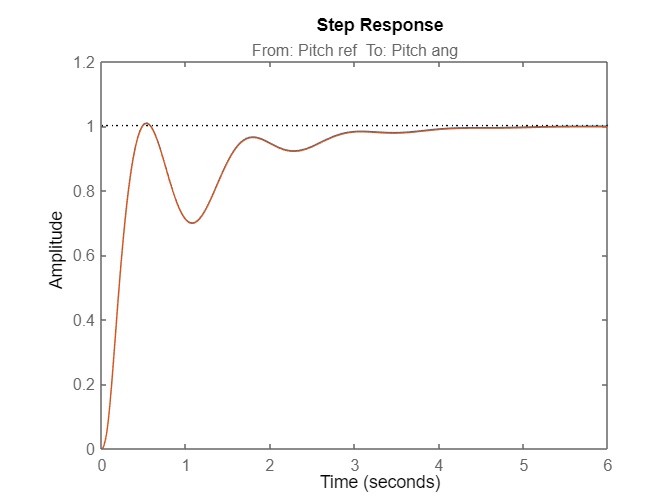

step(minreal(H(2,2),tol)) %pitch
hold on
step(H(2,2)) %roll
hold off

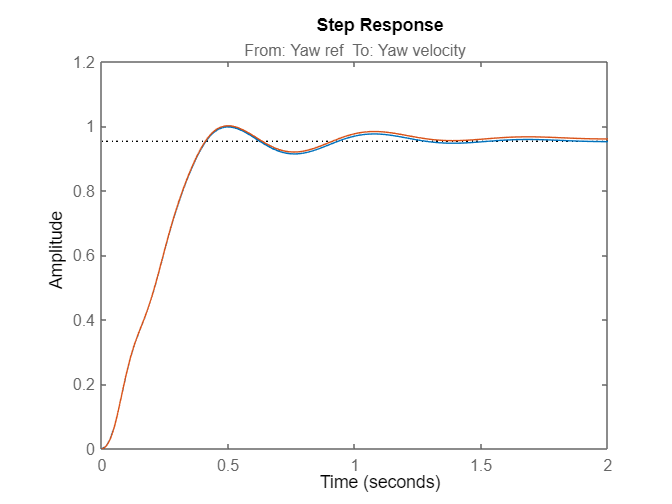

step(minreal(H(3,3),tol)) %yaw
hold on
step(H(3,3)) %roll
hold off

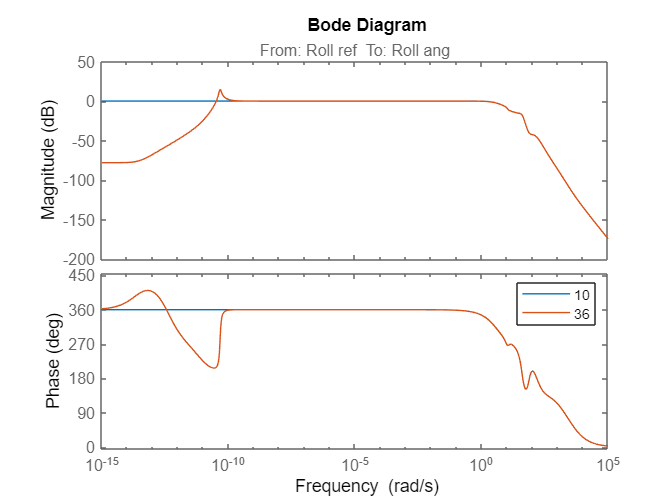

%bode
bode(minreal(H(1,1),tol)) %roll
hold on
bode(H(1,1)) %roll
legend("10","36")
hold off

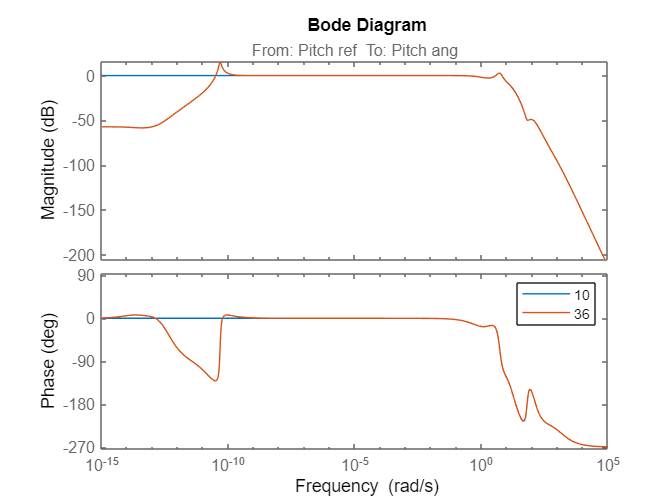

bode(minreal(H(2,2),tol)) %pitch
hold on
bode(H(2,2)) %roll
legend("10","36")
hold off

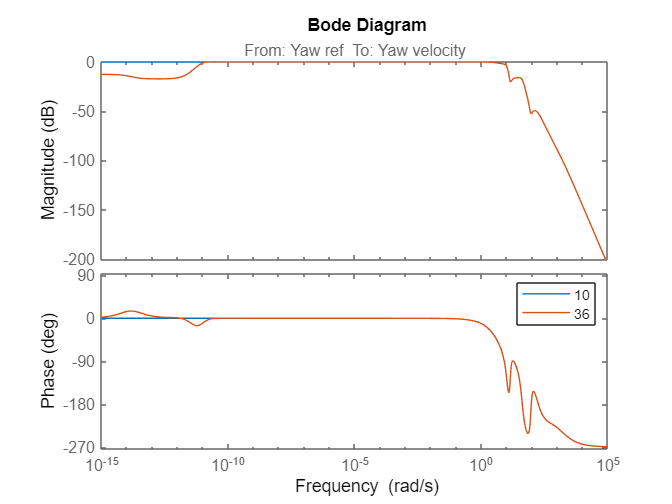

bode(minreal(H(3,3),tol)) %yaw
hold on
bode(H(3,3)) %roll
legend("10","36")
hold off

H_BB=tf(ss9uTest)

Unrecognized function or variable 'ss9uTest'.

pitchData
pitchStepfilt=pitchData(t>=6)*(-1);
plot(t(1:length(pitchStepfilt)),pitchStepfilt,Color="red")
hold on
step(H(2,2)*5) %pitch %pitch
step(H_BB(2,2)*5) %pitch
hold off
legend("unlinear","linear","linearBB")
xlim([0 4])

%cross coupling:
H_yaw_mixer_to_vel=H(3,4)

H_yaw_mixer_to_vel =
 
  From input "Yaw mixer" to output "Yaw velocity":
                                                                                                                                  
   561.7 s^31 + 1.035e06 s^30 + 5.541e08 s^29 + 1.297e11 s^28 + 1.917e13 s^27 + 1.966e15 s^26 + 1.505e17 s^25 + 9.05e18 s^24      
                                                                                                                                  
           + 4.277e20 s^23 + 1.544e22 s^22 + 4.178e23 s^21 + 8.566e24 s^20 + 1.365e26 s^19 + 1.709e27 s^18 + 1.634e28 s^17        
                                                                                                                                  
           + 1.112e29 s^16 + 4.699e29 s^15 + 7.455e29 s^14 - 3.152e30 s^13 - 1.975e31 s^12 - 3.917e31 s^11 - 1.18e31 s^10         
                                                                                                                                  
         

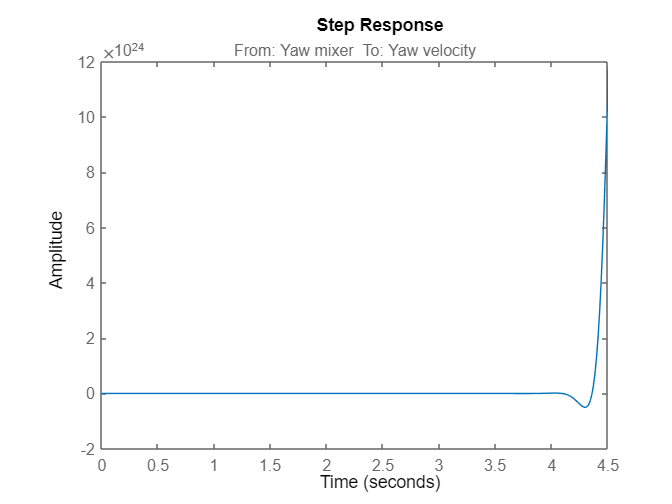

step(H_yaw_mixer_to_vel)